# **Third Optimal Control Project**

# **Design of an LQT controller with integral action for a mass-spring-damper system.**

## Ali Eidizadeh                            ali80ei@gmail.com

## Amirhadi Keyvan     amirhadikeyvan@gmail.com

%% Part B
clc 
clear 
close all
%---    system definition
m1 = 1;
m2 = 1;
c1 = 1;
c2 = 1;
k1 = 1;
k2 = 1;

A = [0              1               0       0;...
    -(k1+k2)/m1     -(c2+c1)/m1     k2/m1   c2/m1;...
    0               0               0       1;...
    k2/m2           c2/m2          -k2/m2  -c2/m2;]

A =      0     1     0     0
    -2    -2     1     1
     0     0     0     1
     1     1    -1    -1


B = [0;0;0;1/m2]

B =      0
     0
     0
     1


C = [1 0 0 0]

C =      1     0     0     0


D = 0

D = 0

%---    controllability analysis
rank(ctrb(A,B))

ans = 4

rank([B A;0 -C])        % integral controllability

ans = 5


%---    Augmented system
Aa = [A zeros(4,1);...
     -C 0]

Aa =      0     1     0     0     0
    -2    -2     1     1     0
     0     0     0     1     0
     1     1    -1    -1     0
    -1     0     0     0     0


Ba = [B;0]

Ba =      0
     0
     0
     1
     0


Ca = [C 0]

Ca =      1     0     0     0     0



%---    LQR
Q = 1*(C'*C);
Q = [Q zeros(4,1);
    zeros(1,4) 100];
R = 0.000000001;
K = lqr(Aa,Ba,Q,R);
K1 = K(1:4)

K1 = 	1.0e+04 *

    5.1335    0.2467    0.0069    0.0070


K2 = K(5)

K2 = -3.1623e+05

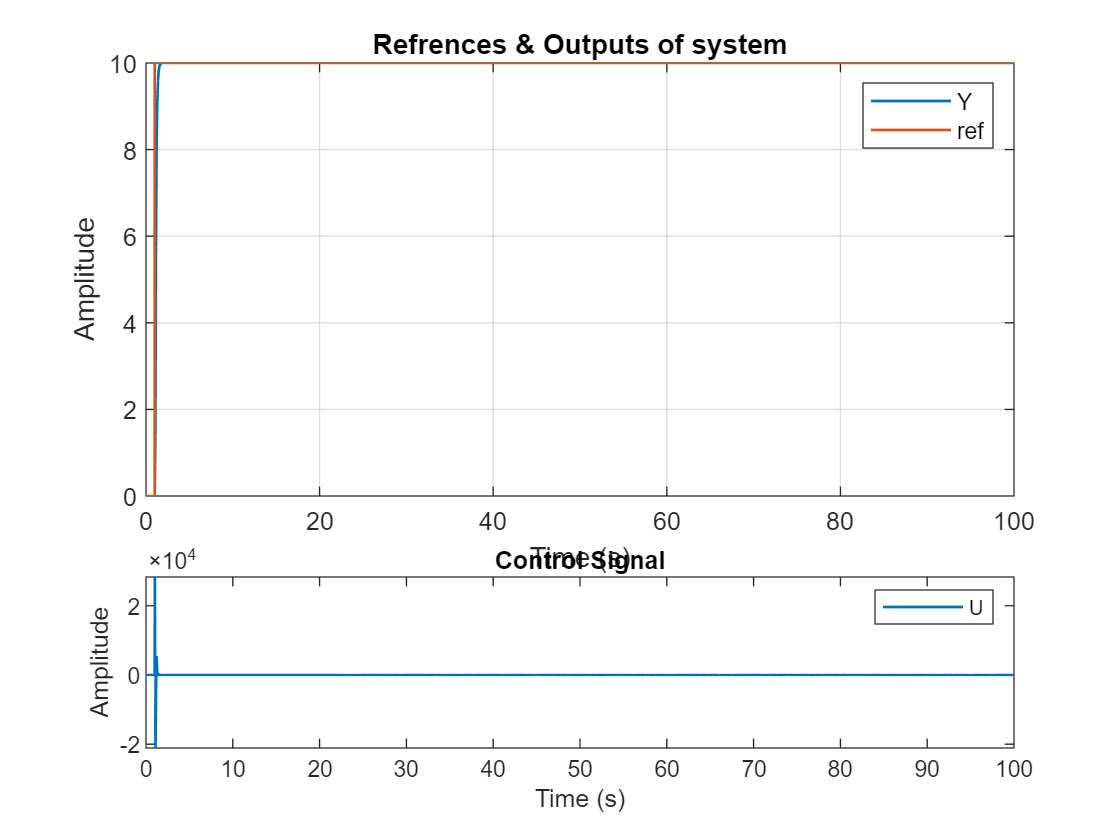


%---    simulink
% Simulation of Closed Loop System
sim('Integral_Control')

% Plotting
figure
subplot(3,1,1:2)
plot(y,'linewidth',1)
hold on
plot(Ref,'linewidth',1)
hold on
grid on
legend('Y','ref')
xlabel('Time (s)')
ylabel('Amplitude')
title('Refrences & Outputs of system')
subplot(3,1,3)
plot(U,'linewidth',1)
legend('U')
xlabel('Time (s)')
ylabel('Amplitude')
title('Control Signal')

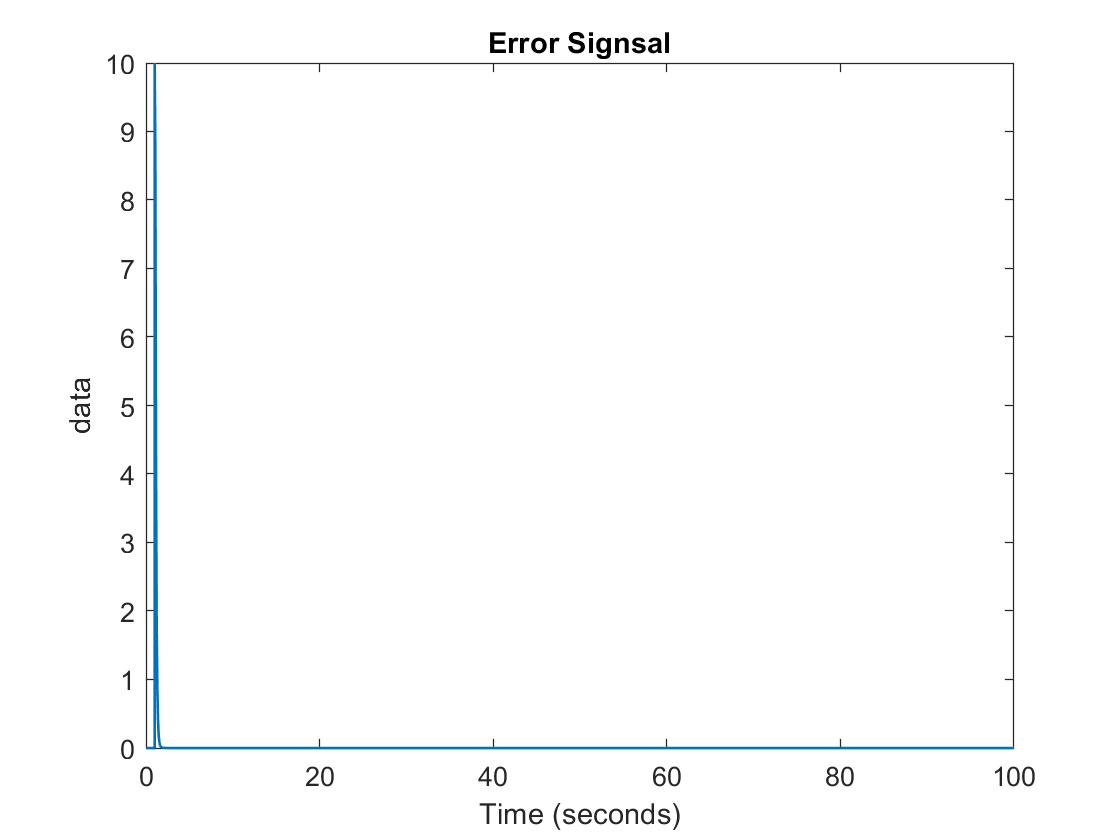


figure
plot(Error,'linewidth',1)
title('Error Signsal')